## Plotting the linear universal array factor in terms of $\psi$

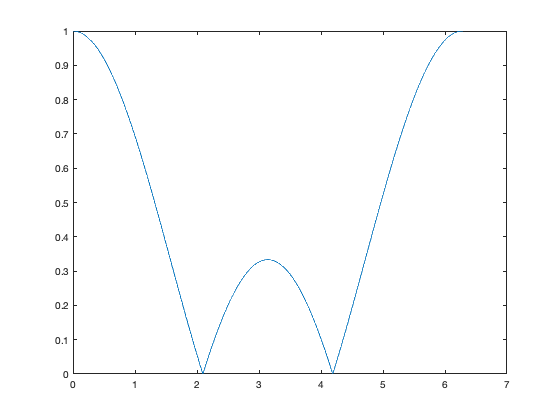

x1 = linspace(0*pi,2*pi,1001);
y = abs(sinc((5*x1)));
N = 3;
y = 1/N*abs((sin(N*x1/2))./(sin(x1/2)));
plot(x1,y)
% matlab2tikz('linear.tex','standalone',true)



## The corresponding polar radiation pattern

d = 0.5;
kd = 2*pi*d;
alpha = 0;
x2 = linspace(0,2*pi,1001);

y1 = 1/N*abs(sin(N/2*(kd*cos((x2))+alpha))./sin((kd*cos((x2))+alpha)/2));
polar(x2,y1)
% matlab2tikz('broadside.tex','standalone',true)

## Non-uniform linear arrays

% Triangular
tri = [1,2,3,2,1];
N = 5;

plot(tri)
% matlab2tikz('triangular_dist.tex','standalone',true)

d_1 = 0.5;
kd_1 = 2*pi*d_1;
alpha_1 = 0;
psi = kd_1 * cos(x2) + alpha_1;
AF = 0;
for i = 1 : N
    AF = AF + tri(i)*exp(1i * i*(psi));
end
polar(x2,abs(AF)/max(abs(AF)))
% matlab2tikz('triangular.tex','standalone',true)

% Binomial 
binomial = [1,4,6,4,1]; % weights
N = 5; % Array size

plot(binomial)
% matlab2tikz('binomial_dist.tex','standalone',true)
d_1 = 0.5;
kd_1 = 2*pi*d_1;
alpha_1 = 0;
psi = kd_1 * cos(x2) + alpha_1;
AF = 0;
for i = 1 : N
    AF = AF + binomial(i)*exp(1i * i*(psi));
end
polar(x2,abs(AF)/max(abs(AF)))
% matlab2tikz('binomial.tex','standalone',true)

% Dolph-Chebyshev
dc = [1,1.61,1.94,1.61,1];
N = 5;

plot(dc)
% matlab2tikz('dc_dist.tex','standalone',true)

d_1 = 0.5;
kd_1 = 2*pi*d_1;
alpha_1 = 0;
psi = kd_1 * cos(x2) + alpha_1;
AF = 0;
for i = 1 : N
    AF = AF + dc(i)*exp(1i * i*(psi));
end
polar(x2,abs(AF)/max(abs(AF)))
% matlab2tikz('dc.tex','standalone',true)

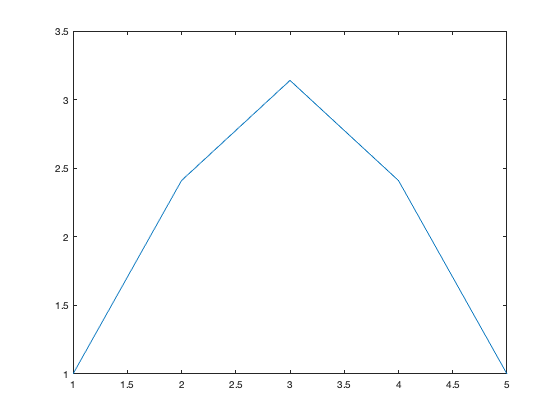

% Dolph-Chebyshev - 2
dc2 = [1,2.41,3.14,2.41,1];
N = 5;

plot(dc2)

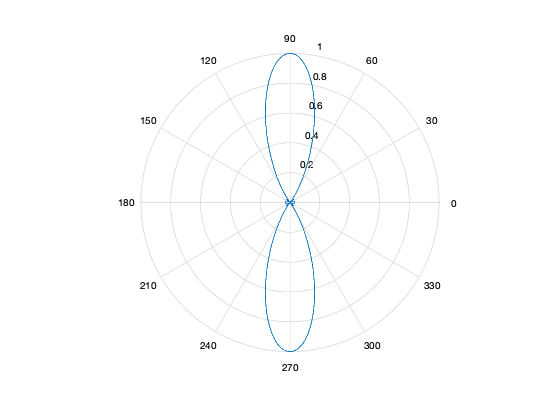

% matlab2tikz('dc2_dist.tex','standalone',true)
d_1 = 0.5;
kd_1 = 2*pi*d_1;
alpha_1 = 0;
psi = kd_1 * cos(x2) + alpha_1;
AF = 0;
for i = 1 : N
    AF = AF + dc2(i)*exp(1i * i*(psi));
end
polar(x2,abs(AF)/max(abs(AF)))

% matlab2tikz('dc2.tex','standalone',true)